# Matlab Introduction: Tables and Functions

We're about to complete our Introduction to Matlab syntax. By the time you've worked through this live script you will know everything you need to know for the rest of the unit.

**Cell arrays**

In part 3 we met the idea that Matlab thinks of all our variables as 2D arrays. Even a variable containing a single number is still a 2D array, it just happens to only contain 1 row and 1 column:

num1 = 7;
size(num1)

ans =      1     1


And Matlab is perfectly comfortable with us writing to new rows and/or columns at any time:

num1(3,4) = 55

num1 =      7     0     0     0
     0     0     0     0
     0     0     0    55


The only limitation Matlab places on us is that each element of our array can only hold either a single number or a single character. For example, when we made the `foo` variable right back in part 1, we were actually creating a 2D array of characters with height 1 and width 3:

foo = 'bar';
size(foo)

ans =      1     3


This is actually a bit of a problem for us. There will be times when we want to do machine learning with features that hold string values rather than numeric values. As a simple example, one popular machine learning dataset contains information about real people, and one of the features is "personal status" which can take any of the following possible values:

- "single male"

- "married male"

- "divorced male"

- "single female"

- "married female"

- "divorced female"

The dataset has 1000 different examples in it and for ease we'd like a way of holding the "personal status" features together in 1000 different elements of a single array (the alternative is to store 1000 differently named variables!).

We can store more complex things (than single numbers or single characters) inside the different elements of our arrays if we first bundle them up inside a *cell*. Have a look at the following example:

% store 3 cells inside our array
% to put something inside a cell, surround it by {}-brackets
% you can put _anything_ inside a cell
myarray = [{'short string'} {'very very long string'} {'different again'}]

myarray = 1×3 cell array
    {'short string'}    {'very very long string'}    {'different again'}


size(myarray)

ans =      1     3


The call to `size()` returns [1 3] meaning our array has a height of 1 (row) and a width of 3 (columns). We have made an array of cells, where each cell holds a differently sized string. Cells and cell array are an extremely useful tool in Matlab, as they allow us to package up *anything* we're working with and store it side-by-side with *anything else*.

When you have an array of cells like the one we have above, you have two options for reading data out of it:

- Using normal braces () to return a cell

- Using curly braces {} to return the contents of a cell

For example:

% this line returns the third cell in the array:
myarray(1,3)

ans = 1×1 cell array
    {'different again'}


% this line returns the contents of the third cell in the array:
myarray{1,3}

ans = 'different again'

So cell arrays are great for the extra flexibility they offer us, but we do have to be a little bit careful when referring to them. Here are two examples:

The first example causes an error because we try to write a new value into the second element of the array of cells, rather than into the cell in the second element of the array of cells. We stop the error from breaking the script by placing it in a try-catch statement. Try-catch statements should be familiar from other languages you've met on this degree, but don't worry if not - we'll rarely use them outside of this example. They just let you guard against errors occuring (in the "try" section) and do sensible things if they do occur (in the "catch" section) instead of having your code break and stop executing:

try
    myarray(1,2) = 'something else'
catch
    fprintf('this would cause an error if we let it\n');
end

this would cause an error if we let it


In the second example we try to delete the second element of the cell array, but accidentally store an empty array inside the cell inside the second element:

myarray{1,2} = []

myarray = 1×3 cell array
    {'short string'}    {0×0 double}    {'different again'}


Both problems are caused by use of the wrong kind of brackets for referring to the cell array. Make sure you can follow what's going wrong in these examples, and complete the tasks below before moving on to the next section.

Task 1:

% create a cell array called c1 that stores: the number 22, the string 'something'
% and the string 'nothing'
% type your solution on the line below:
c1 = [{22} {'something'} {'nothing'}]

c1 = 1×3 cell array
    {[22]}    {'something'}    {'nothing'}


Task 2:

% replace the text inside the third cell of c1 with the text: 'replaced'
% type your solution on the line below:
c1(1,3) = {'replaced'}

c1 = 1×3 cell array
    {[22]}    {'something'}    {'replaced'}


Task 3:

% delete the second element of c1 to reduce the length of the array by 1
% make an appropriate call to the size() function to convince yourself that 
% your approach has worked
% type your solution below:
size(c1)

ans =      1     3


c1(:,2)=[]

c1 = 1×2 cell array
    {[22]}    {'replaced'}


size(c1)

ans =      1     2


## Tables

We're now ready to read in our first machine learning dataset. As with almost all the datasets we'll work with on this unit, we'll read it in from a comma separated values (CSV) file. The file is up on Moodle and you should make sure that you have downloaded it and moved it into the same directory as this script (and that the Matlab Current Folder is set to that same directory).

Before you go any further, have a look at the CSV data by opening it up in Excel. You should see something like this:

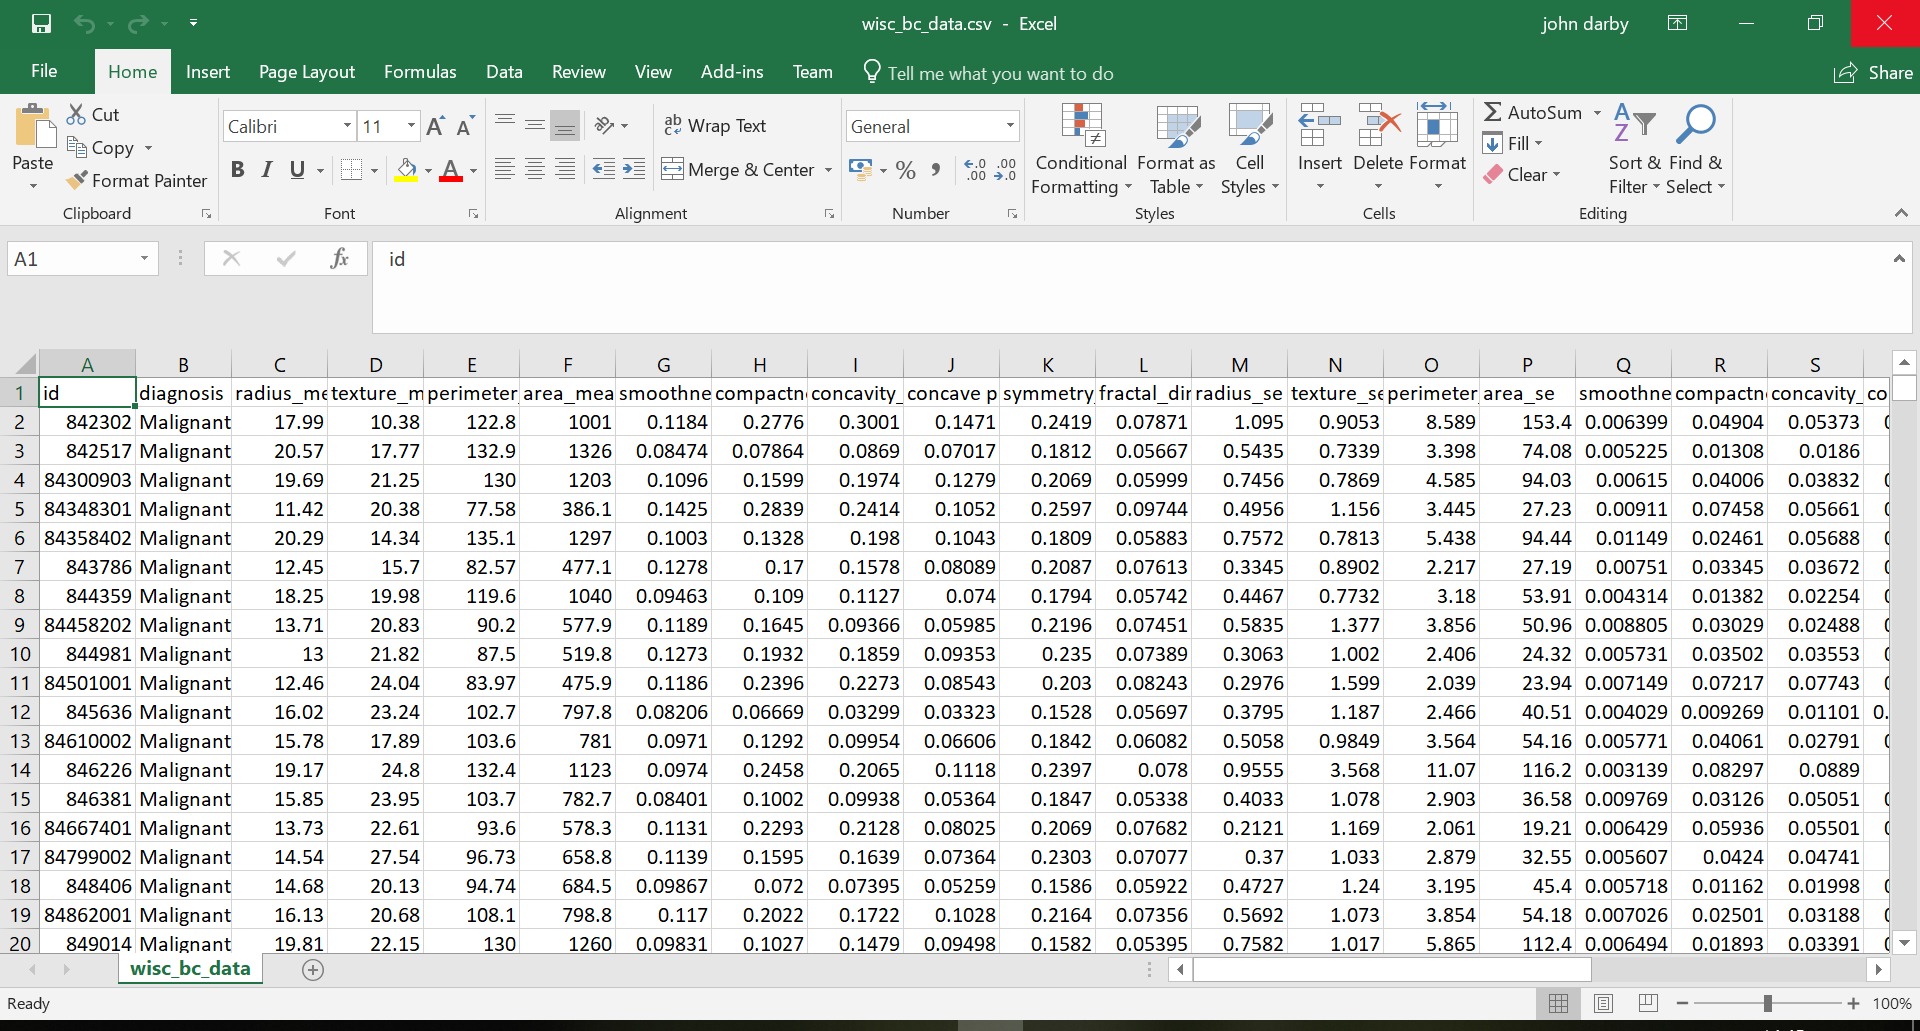

You're looking at each example in the dataset in different rows (there are 569 in total), and all of the features in each example in different columns (there are 32 in total). The names of each feature are given in the row right at the top (have a quick look, but don't worry if they don't make sense). If you have a quick look along all of the features you'll notice they are all numeric except for the "diagnosis" feature which contains strings.

The data describes some simple measurements of cell nuclei drawn from unusual tissue masses in hospital patients, and whether those masses were subsequently found to be cancerous (Malignant) or not (Benign). The challenge in machine learning terms would be to establish whether a reliable connection can be found between the measurements and the diagnosis.

We'd like to read the data into Matlab in a format that's going to make it easy to work with. One option would be to read each feature into a different Matlab array, so that we'd have one array for every column in the image above. The arrays would be of size [569 1]: 569 rows high, only 1 column wide. And they would each be named after the corresponding feature. So the first array would be called "id", the second "diagnosis" and so on. Matlab can do this for us and it can even handle the strings in the "diagnosis" column for us by placing each one inside a cell and making us a cell array for that column.

The problem with this approach is that we end up with 32 big arrays in our Matlab Workspace, which are quite difficult to work with. Each one has a name that probably doesn't mean anything to us, and we have to use these 32 names to refer to arrays in the code we write. It's possible, but it's quite awkward...

What we'd really like is to bring all these columns together in a single big 2D array. 

Based on what we've met so far, we don't have a way to do this because we can't mix cells and things that aren't cells together in the same array. We could put *every* value inside a cell (including numeric values) and make a huge 2D cell array, but these kinds of arrays aren't as easy to read data back out of. (There's an interesting blog post from Mathworks (the creators of Matlab) here if you're interested in finding out more: [https://blogs.mathworks.com/loren/2016/09/26/indexing-with-curly-braces/](https://blogs.mathworks.com/loren/2016/09/26/indexing-with-curly-braces/))

Enter tables...

Matlab *tables* are a new data type (different to the numbers, chars, and cells we've met previously) designed specifically for holding datasets like the one above. As the name suggests, they have a tabular structure with rows and columns, but unlike a normal 2D array they allow you to store different data types in each column. You can then refer to different columns or rows of the table using the indexing techniques we've already introduced (e.g., double-colon notation, logical indexing). To see an example, let's load up the CSV file from above with Matlab's `readtable()` function, which reads a CSV file from disk and puts the data into a table:

t = readtable('wisc_bc_data.csv');

Matlab will give a warning because there are spaces in some of the column headings, but it's nothing to worry about.

Before we look at the data, we need to know a couple of rules about how to access table data. 

Similarly to working with cell arrays, you have two options for reading data out of a table:

- Using normal braces () to return a table

- Using curly braces {} to return the contents of a table

So, first using normal braces, let's copy the first 10 rows of the table into a smaller table and have a look at it:

smalltable = t(1:1:10,1:1:end)

smalltable = 10×32 table
        id         diagnosis     radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    con

Now let's use curly braces to see what kind of data is actually inside each of those table columns:

smalltable{1:1:end, 1} % the id column is a "normal" array containing numeric data

ans =       842302
      842517
    84300903
    84348301
    84358402
      843786
      844359
    84458202
      844981
    84501001


smalltable{1:1:end, 2} % the diagnosis column is a cell array containing string data

ans = 10×1 cell array
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}


Because we're using a table, these different data types (cells and floating-point values) can sit side by side.

Now something that's really nice about tables (and not possible if we'd just taken the "big cell array" approach mentioned above): providing we read data from "like" columns (i.e. columns that store the same data types) we can use curly braces to read the raw data out across multiple rows. For example, here we read all the numeric data out of `smalltable`:

smalltable{1:1:end, [1 3:1:end]}

ans = 	1.0e+07 *

    0.0842    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0843    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    8.4301    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    8.4348    0.0000    0.0000    0.0000    0.000

The numbers in the first ID column are so large makes it hard to see the other values (Matlab automatically puts them all in the same scientific notation: here they're all multiplied up by 10^7). In fact, ID number is a randomised code assigned to each patient in the dataset and it's not really a "feature" at all in the sense that we might be able to extract any kind of useful information from it during machine learning. So let's delete it, and have another look at the data.

Deleting a column from a table is very similar to deleting a column from a "normal" 2D array. We reference the entire column as a table (so using normal brackets), and set it equal to an empty array. As with normal 2D arrays, Matlab will insist that we use the single colon shortcut in the reference (so we can't make a mistake):

smalltable(:, 1) = []; % single colon shortcut required for a deletion
smalltable{1:1:end, 2:1:end}

ans = 	1.0e+03 *

    0.0180    0.0104    0.1228    1.0010    0.0001    0.0003    0.0003    0.0001    0.0002    0.0001    0.0011    0.0009    0.0086    0.1534    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0254    0.0173    0.1846    2.0190    0.0002    0.0007    0.0007    0.0003    0.0005    0.0001
    0.0206    0.0178    0.1329    1.3260    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0005    0.0007    0.0034    0.0741    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0250    0.0234    0.1588    1.9560    0.0001    0.0002    0.0002    0.0002    0.0003    0.0001
    0.0197    0.0213    0.1300    1.2030    0.0001    0.0002    0.0002    0.0001    0.0002    0.0001    0.0007    0.0008    0.0046    0.0940    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0236    0.0255    0.1525    1.7090    0.0001    0.0004    0.0005    0.0002    0.0004    0.0001
    0.0114    0.0204    0.0776    0.3861    0.0001    0.0003    0.0002    0.000

One last useful thing to know about tables is that you can index into the columns using their names. Have a look at the following commands:

smalltable(1:1:end, 'diagnosis') % get the table

ans = 10×1 table
     diagnosis 
    ___________

    'Malignant'
    'Malignant'
    'Malignant'
    'Malignant'
    'Malignant'
    'Malignant'
    'Malignant'
    'Malignant'
    'Malignant'
    'Malignant'


smalltable{1:1:end, 'diagnosis'} % get the data

ans = 10×1 cell array
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}


And you can also index multiple columns at once in this way, but the references to the column titles have to be stored in a cell array:

smalltable(1:1:end, [{'radius_mean'}, {'texture_mean'}]) % get the table

ans = 10×2 table
    radius_mean    texture_mean
    ___________    ____________

       17.99          10.38    
       20.57          17.77    
       19.69          21.25    
       11.42          20.38    
       20.29          14.34    
       12.45           15.7    
       18.25          19.98    
       13.71          20.83    
          13          21.82    
       12.46          24.04    


smalltable{1:1:end, [{'radius_mean'}, {'texture_mean'}]} % get the data

ans =    17.9900   10.3800
   20.5700   17.7700
   19.6900   21.2500
   11.4200   20.3800
   20.2900   14.3400
   12.4500   15.7000
   18.2500   19.9800
   13.7100   20.8300
   13.0000   21.8200
   12.4600   24.0400


So, in summary, tables are great for handling the kind of data we need for machine learning. But there was a lot we needed to understand about Matlab before we could introduce them. Hopefully, you'll feel confident using them because of the thorough way in which we've built up to them.

Task 1:

% take a copy of smalltable called smalltable2
% type your solution on the line below:
smalltable2 = smalltable

smalltable2 = 10×31 table
     diagnosis     radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavity_worst    

Task 2:

% copy the "radius_mean" and "texture_mean" columns of smalltable2 into
% a numeric 2D array (not a table) called a1
% type your solution on the line below:
a1 = smalltable2{:, [{'radius_mean'}, {'texture_mean'}]}

a1 =    17.9900   10.3800
   20.5700   17.7700
   19.6900   21.2500
   11.4200   20.3800
   20.2900   14.3400
   12.4500   15.7000
   18.2500   19.9800
   13.7100   20.8300
   13.0000   21.8200
   12.4600   24.0400


Task 3:

% copy the "diagnosis" and "radius_mean" columns of smalltable2 into
% a table called t1
% type your solution on the line below:
t1 = smalltable2(:, [{'diagnosis'},{'radius_mean'}])

t1 = 10×2 table
     diagnosis     radius_mean
    ___________    ___________

    'Malignant'       17.99   
    'Malignant'       20.57   
    'Malignant'       19.69   
    'Malignant'       11.42   
    'Malignant'       20.29   
    'Malignant'       12.45   
    'Malignant'       18.25   
    'Malignant'       13.71   
    'Malignant'          13   
    'Malignant'       12.46   


Task 4:

% change the "area_mean" value for the 3rd example in smalltable2 to 3021
% type your solution on the line below:
smalltable2{3,'area_mean'} = 3021

smalltable2 = 10×31 table
     diagnosis     radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavity_worst    

Task 5:

% copy the "diagnosis" column of smalltable2 into a cell array (not a table)
% called labels
% type your solution on the line below:
diagarray = smalltable2{:,'diagnosis'}

diagarray = 10×1 cell array
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}
    {'Malignant'}


Task 6:

% delete the "diagnosis" column from smalltable2
% type your solution on the line below:
smalltable2(:,'diagnosis') = []

smalltable2 = 10×30 table
    radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavity_worst    concavePoints_worst 

## Sorting tables

It can sometimes be useful to sort the contents of a table based on a particular variable. The function `sortrows()` allows you to do this. Have a look at the following example, which sorts `smalltable` based on the values in the radius_mean column:

sortrows(smalltable, 'radius_mean')

ans = 10×31 table
     diagnosis     radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concavePoints_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concavePoints_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    concavity_worst    conca

## Summarising table data

A useful command when working with tables is the `summary()` function, which prints out a text-based summary of a table's structure and contents. See the following example, which passes the original table to the `summary()` function, and take some time to scroll through and read the output that it produces:

summary(t)


Variables:

    id: 569×1 double

        Values:

            Min             8670
            Median    9.0602e+05
            Max       9.1132e+08

    diagnosis: 569×1 cell array of character vectors

    radius_mean: 569×1 double

        Values:

            Min           6.981    
            Median        13.37    
            Max           28.11    

    texture_mean: 569×1 double

        Values:

            Min            9.71     
            Median        18.84     
            Max           39.28     

    perimeter_mean: 569×1 double

        Values:

            Min            43.79      
            Median         86.24      
            Max            188.5      

    area_mean: 569×1 double

        Values:

            Min          143.5   
            Median       551.1   
            Max           2501   

    smoothness_mean: 569×1 double

    

## Categorical data

Remember that when Matlab loaded the diagnosis column, it loaded it as a cell array where each cell contained an array of chars. As an example, the line of code below displays the char data inside the very first cell in the array:

t{1,'diagnosis'}

ans = 1×1 cell array
    {'Malignant'}


There's nothing wrong with this approach to storing the data, but it does miss something useful about that column: there are only two possible values that it can hold - either 'Malignant' or 'Benign'. This kind of data is called *categorical *data: there are only a fixed number of values - or categories - that the data can take. Matlab offers a specific type of array for holding this kind of data: a *categorical array*. 

If we bother to convert our data into a categorical array then we get some benefits that we wouldn't get if we just left it as a cell array. These things include the ability to pass it to mathematical functions that would otherwise give an error, for example `mode()` to compute the most common value, and the ability to call the `summary()` function we met above to display a text-based summary of the data. Let's have a look. In the line below, we take a copy of the diagnosis column and convert it into a categorical variable:

diagnosis_categorical = categorical(t{1:1:end,'diagnosis'});

We can then compute it's mode (most common value):

mode(diagnosis_categorical)

ans = categorical
     Benign 


And view a helpful summary which tells us how many examples of 'Malignant' and 'Benign' samples are in our table:

summary(diagnosis_categorical);

     Benign         357 
     Malignant      212 


Both these functions will be useful to us later in the unit, and we'll use categorical arrays in order to have access to them.

## Tasks

The file "ilpd.csv" contains a similar dataset to the one we've been working with above. This time the data contains the ages and blood sample results for a group of patients, and whether the patients were subsequently found to be suffering from liver disease, or not. The challenge in machine learning terms would be to establish whether a reliable connection can be found between the measurements and the diagnosis.

Task 1:

% load the ilpd.csv dataset into a table named ilpd
% type your solution on the line below:
ilpd = readtable('ilpd.csv')

ilpd = 583×10 table
    age    tot_bilirubin    direct_bilirubin    tot_proteins    albumin    ag_ratio    sgpt    sgot    alkphos    diagnosis 
    ___    _____________    ________________    ____________    _______    ________    ____    ____    _______    __________

    65          0.7               0.1               187           16          18       6.8     3.3       0.9      'healthy' 
    62         10.9               5.5               699           64         100       7.5     3.2      0.74      'healthy' 
    62          7.3               4.1               490           60          68         7     3.3      0.89      'healthy' 
    58        

Task 2:

% display a summary of the ilpd table
% type your solution on the line below:
summary(ilpd)


Variables:

    age: 583×1 double

        Values:

            Min         4  
            Median     45  
            Max        90  

    tot_bilirubin: 583×1 double

        Values:

            Min             0.4      
            Median            1      
            Max              75      

    direct_bilirubin: 583×1 double

        Values:

            Min               0.1       
            Median            0.3       
            Max              19.7       

    tot_proteins: 583×1 double

        Values:

            Min              63     
            Median          208     
            Max            2110     

    albumin: 583×1 double

        Values:

            Min           10   
            Median        35   
            Max         2000   

    ag_ratio: 583×1 double

        Values:

            Min            10   
            Median         42   
     

Task 3:

% sort the examples in the ilpd table based on the patients' age
% type your solution on the line below:
sortrows(ilpd,'age')

ans = 583×10 table
    age    tot_bilirubin    direct_bilirubin    tot_proteins    albumin    ag_ratio    sgpt    sgot    alkphos    diagnosis 
    ___    _____________    ________________    ____________    _______    ________    ____    ____    _______    __________

     4          0.9                0.2               348           30          34        8       4         1      'diseased'
     4          0.8                0.2               460          152         231      6.5     3.2       0.9      'diseased'
     6          0.6                0.1               289           38          30      4.8       2       0.7      'diseased'
     7         

Task 4:

% copy the contents of the diagnosis column into a categorical array called diag_c
% type your solution on the line below:
diag_c = categorical(ilpd{:,'diagnosis'})

diag_c = 583×1 categorical array
     healthy 
     healthy 
     healthy 
     healthy 
     healthy 
     healthy 
     healthy 
     healthy 
     diseased 
     healthy 
     healthy 
     healthy 
     diseased 
     healthy 
     healthy 
     diseased 
     healthy 
     diseased 
     healthy 
     healthy 
     healthy 
     healthy 
     healthy 
     healthy 
     diseased 
     healthy 
     healthy 
     healthy 
     diseased 
     diseased 
     healthy 
     healthy 
     diseased 
     diseased 
     diseased 
     healthy 
     diseased 
     healthy 
     healthy 
     healthy 
     healthy 
     diseased 
     diseased 
     healthy 
     diseased 
     diseased 
     healthy 
     healthy 
     healthy 
     healthy 
     healthy 
     healthy 
     healthy 
     healthy 
     healthy 
     healthy 
     diseased 
     diseased 
     healthy 
     diseased 
     healthy 
     healthy 
     healthy 
     healthy 
     healthy 
     healthy 
     healthy 
     health

Task 5:

% delete the diagnosis column from the ilpd table
% type your solution on the line below:
ilpd(:,'diagnosis') = []

ilpd = 583×9 table
    age    tot_bilirubin    direct_bilirubin    tot_proteins    albumin    ag_ratio    sgpt    sgot    alkphos
    ___    _____________    ________________    ____________    _______    ________    ____    ____    _______

    65          0.7               0.1               187           16          18       6.8     3.3       0.9  
    62         10.9               5.5               699           64         100       7.5     3.2      0.74  
    62          7.3               4.1               490           60          68         7     3.3      0.89  
    58            1               0.4               182           14          20       6.8     3.4         1  
    72  

Task 7:

% display a summary of the diag_c array
% type your solution on the line below:
summary(diag_c)

     diseased      167 
     healthy       416 


Task 8:

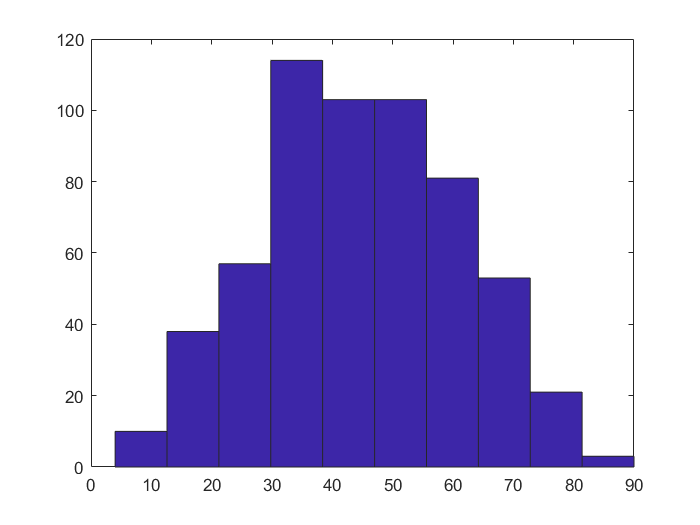

% extract the data from the age column of the ilpd table and pass it to the 
% built-in hist() function to plot a histgram of all the patients' ages
% add suitable titles to the axes of your graph
% type your solution below:
hist(ilpd{:,'age'})

Task 9:

% use logical indexing to create a new table called 
% t2 that only contains the patients aged 50 and over
% type your solution on the line below:
t2 = ilpd((ilpd.age>=50),:) 

t2 = 230×9 table
    age    tot_bilirubin    direct_bilirubin    tot_proteins    albumin    ag_ratio    sgpt    sgot    alkphos
    ___    _____________    ________________    ____________    _______    ________    ____    ____    _______

    65          0.7               0.1               187            16         18       6.8     3.3       0.9  
    62         10.9               5.5               699            64        100       7.5     3.2      0.74  
    62          7.3               4.1               490            60         68         7     3.3      0.89  
    58            1               0.4               182            14         20       6.8     3.4         1  
    72    